# Leitura da imagem em RGB

I = imread('FundusImages/RET002OD.jpg');
I = imresize(I, [256, 256]);
HSV = rgb2hsv(I);

% hsvEq = histeq(HSV(:,:,3));
% HSV(:,:,3) = hsvEq;
% I = hsv2rgb(HSV);

## Mostrar imagem original

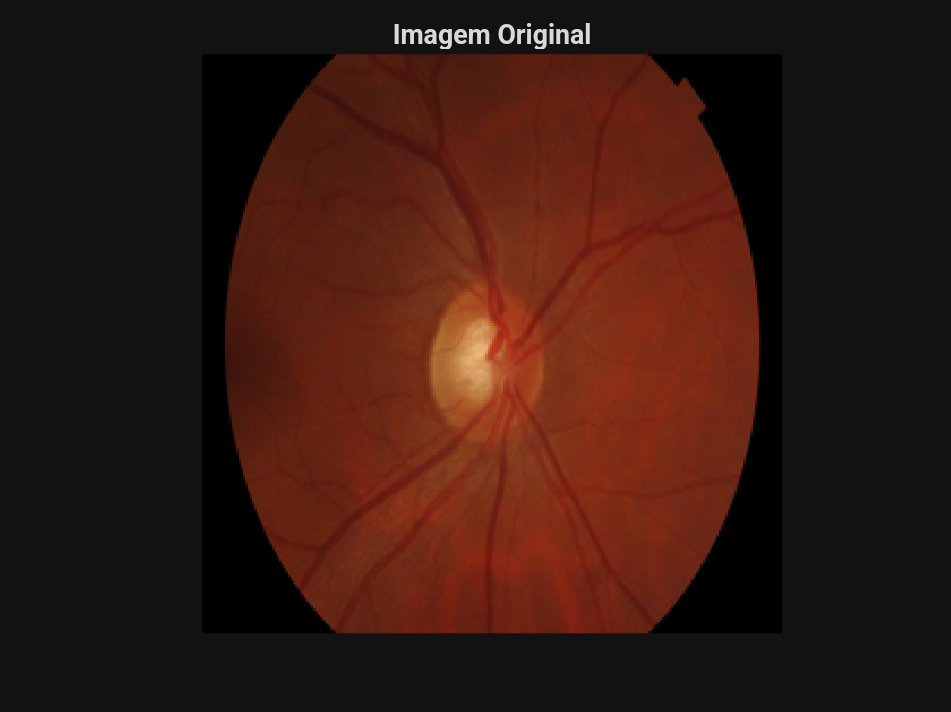

figure;
imshow(I);
title('Imagem Original');

## Reformatar a imagem para aplicar o K-Means

pixel_values = double(reshape(I, [], 3));  


## Alterar número de Clusters

k = 3;


## Aplicar K-Means

[labels, centers] = kmeans(pixel_values, k, 'MaxIter', 100, 'Replicates', 5);


## Reconstruir imagem segmentada

segmented_data = uint8(centers(labels, :));
segmented_image = reshape(segmented_data, size(I));

## Mostrar imagem segmentada

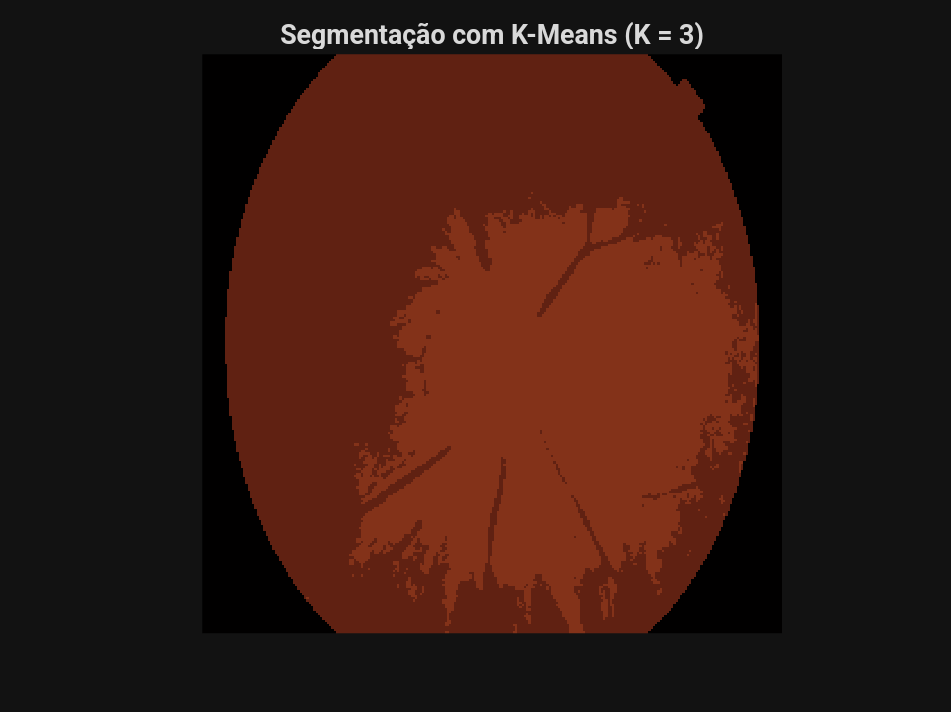

figure;
imshow(segmented_image);
title(sprintf('Segmentação com K-Means (K = %d)', k));

## Identificar cluster mais brilhante (disco óptico costuma ser mais claro)

brightness = sum(centers, 2);
[~, brightest_cluster] = max(brightness);


## Criar máscara binária do cluster mais claro

labels_reshaped = reshape(labels, size(I, 1), size(I, 2));
mask = uint8(labels_reshaped == brightest_cluster);


## Mostrar máscara

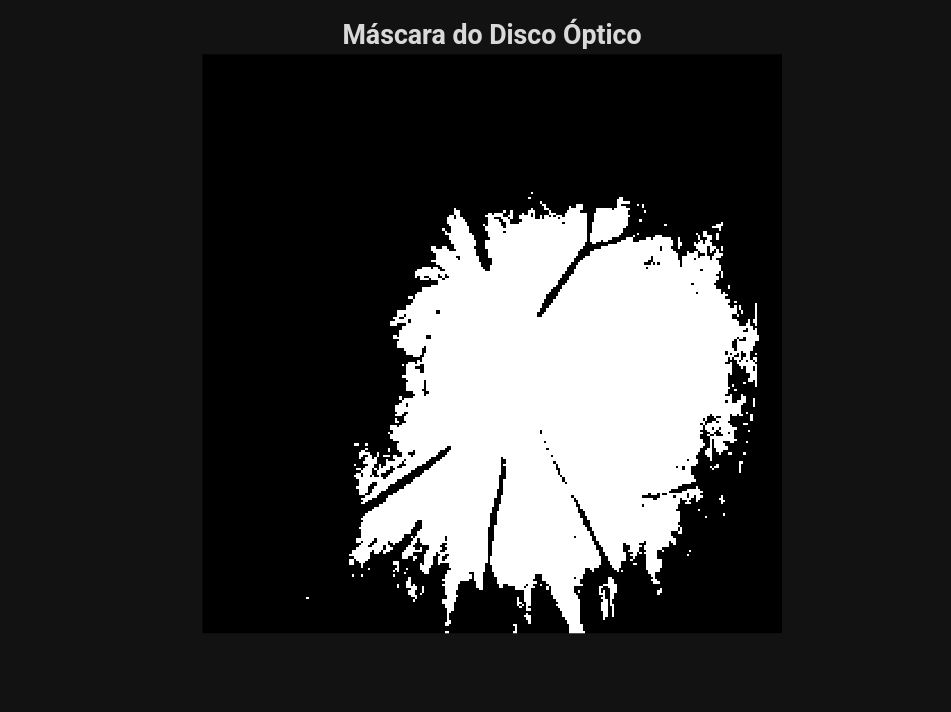

figure;
imshow(mask * 255);
title('Máscara do Disco Óptico');

## Detectar bordas com Canny

edges = edge(mask, 'Canny');


## Mostrar bordas

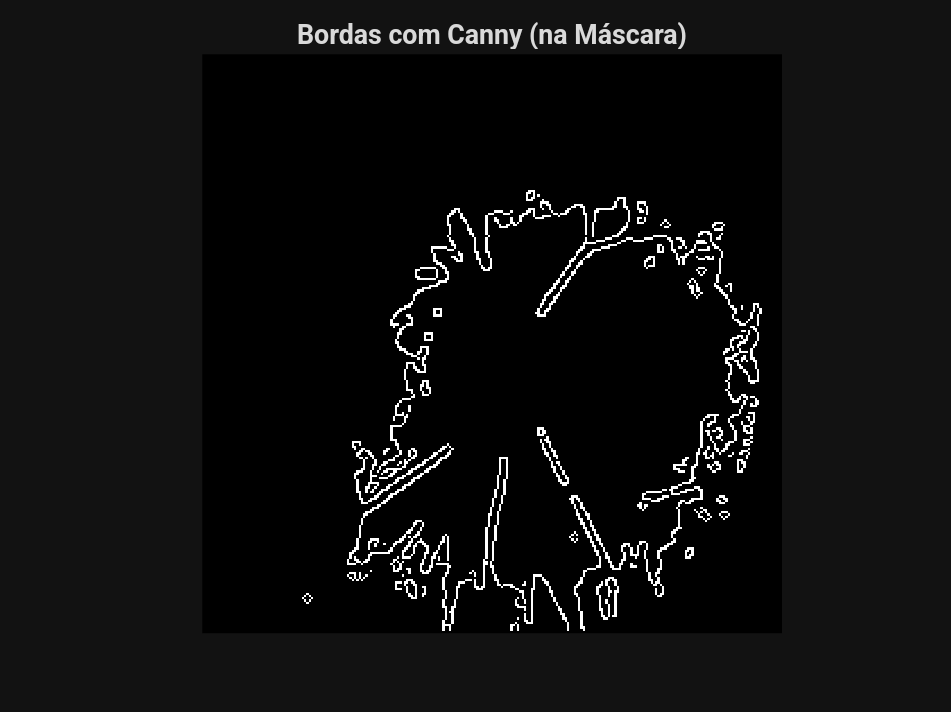

figure;
imshow(edges);
title('Bordas com Canny (na Máscara)');

## Aplicar a máscara sobre a imagem original para isolar o disco óptico

isolated_disc = I;
for c = 1:3
    channel = isolated_disc(:,:,c);
    channel(~mask) = 0;  
    isolated_disc(:,:,c) = channel;a
end


## Mostrar disco óptico isolado

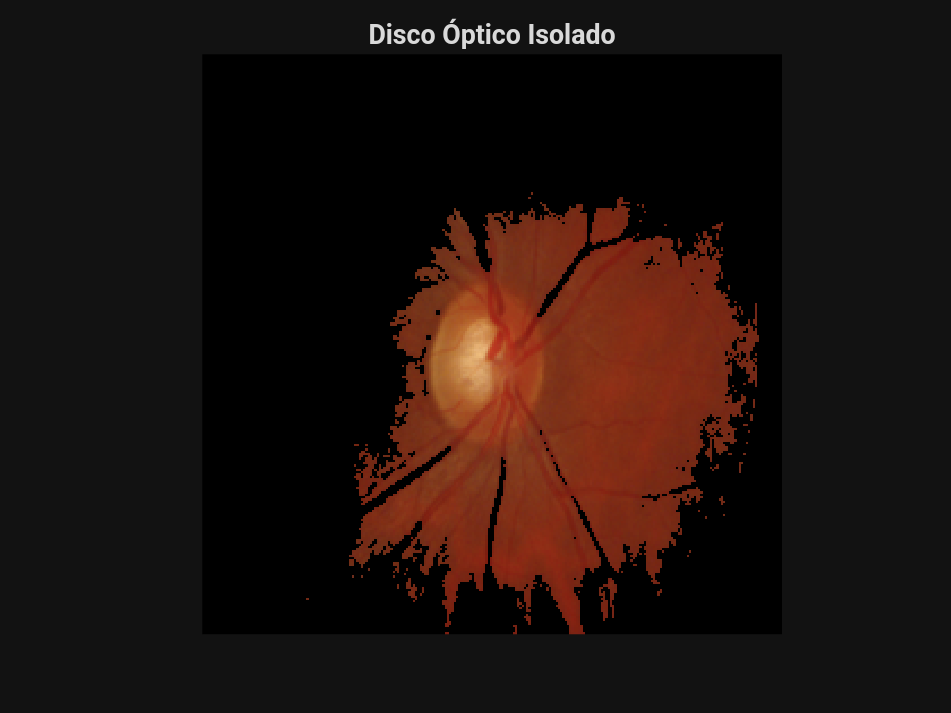

figure;
imshow(isolated_disc);
title('Disco Óptico Isolado');